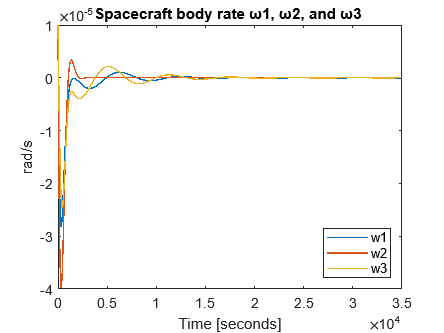

w0=0.0011; % Orbital rate [rad/s]

Mf=7.9*10^15; % Magneti field's dipole strength [Wbm]

J1=250;
J2=150;
J3=100;
J=diag([J1 J2 J3]); % Spacecraft inertia matrix

Jw1=2.5;
Jw2=1.5;
Jw3=1;
Jw=diag([Jw1 Jw2 Jw3]); % Reaction wheel inertia matrix

Q=diag([0.001 0.001 0.001 0.001 0.001 0.001 0.02 0.02 0.02]);
R=diag([1000 1000 1000 100 100 100]);

a=657000;
 A13=w0*(J1-J2+J3)/(-J1);
A16=(w0*Jw3)/(-J1);
A17=8*(w0^2)*(J3-J2)/J1;
A28=6*(w0^2)*(J3-J1)/J2;
A31=w0*(J1-J2+J3)/(J3);
 A34=(w0*Jw1)/(J3);
A39=2*(w0^2)*(J1-J2)/J3;

A=[0 0 A13 0 0 A16 A17 0 0;0 0 0 0 0 0 0 A28 0;A31 0 0 A34 0 0 0 0 A39;0 0 0 0 0 0 0 0 0;0 0 0 0 0 0 0 0 0;0 0 0 0 0 0 0 0 0;
0.5 0 0 0 0 0 0 0 0;0 0.5 0 0 0 0 0 0 0;0 0 0.5 0 0 0 0 0 0]; % vpa for more

% precise values

im = 0; % Orbital inclination [rad]

%b1=(Mf/(a^3))*cos(w0*t)*sin(im)
 %b2=(-(Mf/(a^3))*cos(im))
 %b3=2*(Mf/(a^3))*sin(w0*t)*sin(im)

b1=0;
 b2=-(Mf/(a^3));
 b3=0;

B11=1/J1;
B15=b3/J1;
B16=-b2/J1;
B22=1/J2;
B24=-b3/J2;
 B26=b1/J2;
B33=1/J3;
B34=b2/J3;
 B35=-b1/J3;
B41=1/Jw1;
B52=1/Jw2;B63=1/Jw3;

B=[B11 0 0 0 B15 B16;0 B22 0 B24 0 B26;0 0 B33 B34 B35 0;B41 0 0 0 0 0;0 B52 0 0 0 0;0 0 B63 0 0 0;0 0 0 0 0 0;0 0 0 0 0 0;0 0 0 0 0 0];
D=zeros(9,6);
 %[P,L,G] = dare(A,B,Q,R); % Solution of disrete-time algebric
% Riccati equation

%K=(inv(R+(transpose(B))*P*B))*(transpose(B))*P*A % Control gain

[K,P,E] = lqr(A,B,Q,R);

%u=K*x; % Control law
AUG=A-B*K;
sys=ss((AUG),eye(9),eye(9),eye(9));
 v=[0.00001;0.00001;0.00001;0.00001;0.00001;0.00001;0.01;0.01;0.01];
t = 0:1:35000;
 x = initial(sys,v,t);

x1 = [1 0 0 0 0 0 0 0 0]*x';
x2 = [0 1 0 0 0 0 0 0 0]*x';
 x3 = [0 0 1 0 0 0 0 0 0]*x';
 x4 = [0 0 0 1 0 0 0 0 0]*x';
 x5 = [0 0 0 0 1 0 0 0 0]*x';
 x6 = [0 0 0 0 0 1 0 0 0]*x';
 x7 = [0 0 0 0 0 0 1 0 0]*x';
 x8 = [0 0 0 0 0 0 0 1 0]*x';
x9 = [0 0 0 0 0 0 0 0 1]*x';

plot(t,x1,"LineWidth",1)
hold on
 plot(t,x2,"LineWidth",1)
 hold on
 plot(t,x3,"LineWidth",1)
 hold off

title('Spacecraft body rate ω1, ω2, and ω3 ')
 xlabel('Time [seconds]')
 ylabel('rad/s')
 legend({'w1', 'w2', 'w3'},'Location','southeast')

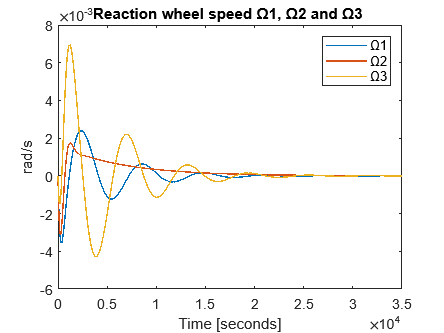


plot(t,x4,"LineWidth",1)
 hold on
 plot(t,x5,"LineWidth",1)
 hold on
 plot(t,x6,"LineWidth",1)
 hold off

title('Reaction wheel speed Ω1, Ω2 and Ω3 ')
 xlabel('Time [seconds]')
 ylabel('rad/s')
 legend({'Ω1', 'Ω2', 'Ω3'},'Location','northeast')

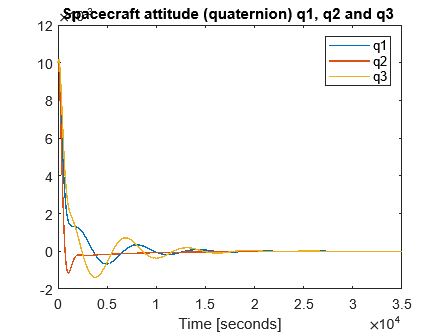


plot(t,x7,"LineWidth",1)
 hold on
 plot(t,x8,"LineWidth",1)
 hold on
 plot(t,x9,"LineWidth",1)
 hold off

title('Spacecraft attitude (quaternion) q1, q2 and q3 ')
 xlabel('Time [seconds]')
 %ylabel('rad/s')
 legend({'q1', 'q2', 'q3'},'Location','northeast')